# 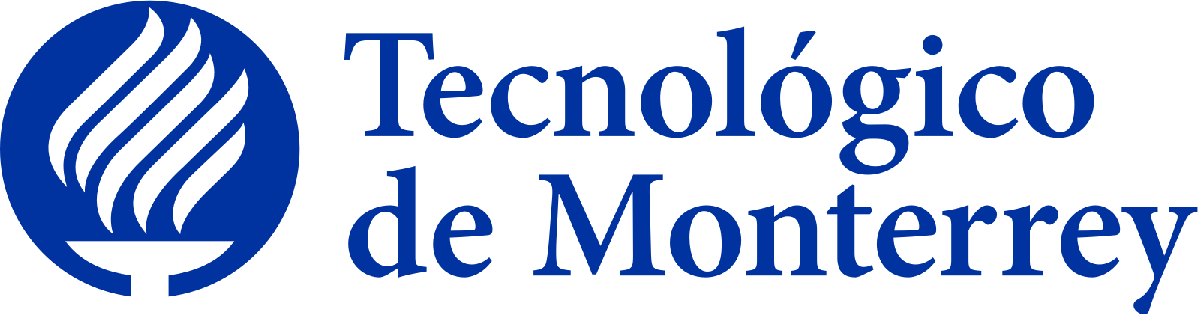

# Segundo Avance del Reto

### Modelación computacional de sistemas eléctricos

Grupo: #210  Equipo: #

Entrega: Abril 15, 2024

Santiago Quintana Moreno A01571222,             Diego Saldaña Gómez A01571609

Natalia Cavazos Almeida A01571724,               Eduardo Vega A0119887

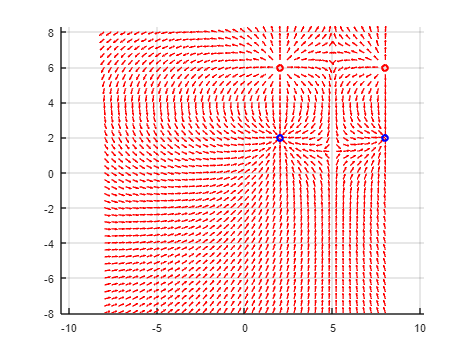

orientacion = input('Introduzca la orientación vertical (v) o horizontal (h): ', 's');
Q = input('Introduzca el valor de la carga: ');
xi = input('Introduzca la coordenada inicial en x: ');
yi = input('Introduzca la coordenada inicial en y: ');
sep = input('Introduzca la separación de los dipolos: ');
dis = 4; % Fixed distance between dipole charges
long = 8; % How far to extend the line of dipoles
[xG, yG] = meshgrid(-8:0.4:8);
hold on;
U = zeros(size(xG));
V = zeros(size(yG));
Qp = Q;
Qn = -Q;
K = 8.99e9; % Coulomb's constant

if(orientacion == 'h')
    Mx1 = xi:sep:xi+long; % x-coordinates for negative charges
    Ny1 = yi*ones(size(Mx1)); % y-coordinates for negative charges
    Mx2 = Mx1; % x-coordinates for positive charges
    Ny2 = (yi+dis)*ones(size(Mx1)); % y-coordinates for positive charges
elseif(orientacion == 'v')
    Ny1 = yi:sep:yi+long; % y-coordinates for negative charges
    Mx1 = xi*ones(size(Ny1)); % x-coordinates for negative charges
    Ny2 = Ny1; % y-coordinates for positive charges
    Mx2 = (xi+dis)*ones(size(Ny1)); % x-coordinates for positive charges
end

for i = 1:length(Mx1)
    % Negative charge contribution
    Rx = xG-Mx1(i);
    Ry = yG - Ny1(i);
    R = sqrt(Rx.^2 + Ry.^2).^3;
    Ex = K.*Qn.*Rx./R;
    Ey = K.*Qn.*Ry./R;

    % Positive charge contribution
    Rx = xG - Mx2(i);
    Ry = yG - Ny2(i);
    R = sqrt(Rx.^2+Ry.^2).^3;
    Ex = Ex + K.*Qp.*Rx./R;
    Ey = Ey + K.*Qp.*Ry./R;
    
    % Accumulate the electric field vectors
    U = U + Ex;
    V = V + Ey;
end

% Normalize vectors for better visualization
magnitude = sqrt(U.^2 + V.^2);
U = U ./ magnitude;
V = V ./ magnitude;

h = quiver(xG, yG, U, V, 'AutoScaleFactor', 0.6);
set(h, 'Color', [1 0 0], 'LineWidth', 1.2);
plot(Mx1, Ny1, 'ob', 'MarkerSize', 5, 'LineWidth', 2);
plot(Mx2, Ny2, 'or', 'MarkerSize', 5, 'LineWidth', 2);
axis equal;
grid on;